# Лабораторная работа №1 по СУвЭ

## Линейный оптиум

lin.Tu = 0.0116

lin = struct with fields:
    Tu: 0.0116


%0.01 + 0.005*(rand()-0.5) 
save('data.mat', 'lin')

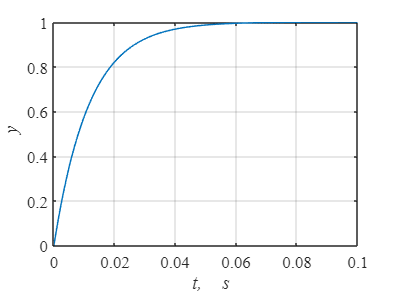

load("data.mat")
Tmdl = 0.1;
k = 1;

warning off
SimNew = sim('lin121.slx', 'ReturnWorkspaceOutputs','on');
warning on

t = SimNew.y(:,1);
y = SimNew.y(:,2);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,y,'Linewidth', 1)
hold on
grid on
xlabel('\it t,\rm \it s')
ylabel('\it y')

Время переходного процесса для входа в 5% зону t_tr

y0 = y(1);
yss = y(end);
D = 0.05*abs(y0-yss);
ind = abs(y-yss)>D;
h=figure;
%plot(t(ind), y(ind), 'LineWidth', 1)
tn = t(ind);
t0 = t(1);
t_tr = tn(end)-t0

t_tr = 0.0343

Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss)

dy = 0

Время переходного процесса для входа в 2% зону t_tr

D2 = 0.02*abs(y0-yss);
ind = abs(y-yss)>D2;
h=figure;
%plot(t(ind), y(ind), 'LineWidth', 1)
tn = t(ind);
t0 = t(1);
t_tr2 = tn(end)-t0

t_tr2 = 0.0443

Реакция на лийнейно-возрастающие воздействие

load("data.mat")
Tmdl = 0.1;
k = 2;

warning off
SimNew = sim('lin121.slx', 'ReturnWorkspaceOutputs','on');
warning on

t = SimNew.y(:,1);
y = SimNew.y(:,2);
g = SimNew.y(:,3);
er = g-y;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

ax(1) = subplot(2,1,1)

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.5838 0.7750 0.3412]
            Units: 'normalized'

  Show all properties


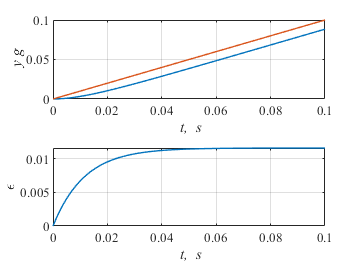

plot(t,y,'Linewidth', 1)
hold on
grid on
plot(t,g,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\it y\rm \itg')

ax(2) = subplot(2,1,2);
plot(t,er,'Linewidth', 1)
hold on
grid on
xlabel('\it t,\rm \it s')
ylabel('\epsilon')

linkaxes(ax, 'x')

Реакция на квадратичное воздействие

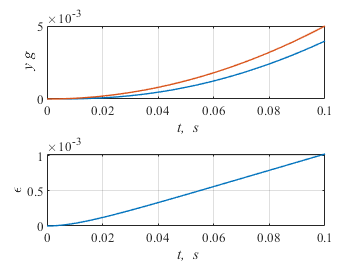

load("data.mat")
Tmdl = 0.1;
k = 3;

warning off
SimNew = sim('lin121.slx', 'ReturnWorkspaceOutputs','on');
warning on

t = SimNew.y(:,1);
y = SimNew.y(:,2);
g = SimNew.y(:,3);
er = g-y;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

ax(1) = subplot(2,1,1);
plot(t,y,'Linewidth', 1)
hold on
grid on
plot(t,g,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\it y\rm \itg')

ax(2) = subplot(2,1,2);
plot(t,er,'Linewidth', 1)
hold on
grid on
xlabel('\it t,\rm \it s')
ylabel('\epsilon')

linkaxes(ax, 'x')%привязывает оси, при увеличении графика верхнего, нижний тоже увеличивается

Запас по амплитуде, по фазе 

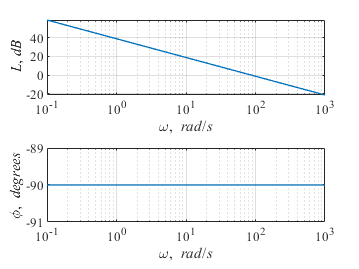

w = 10.^(-1:0.1:3);
s = 1i*w;
lin.Wop = 1./(lin.Tu*s);
Lw = 20*log10(abs(lin.Wop));
phi = angle(lin.Wop)*180/pi;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

ax(1) = subplot(2,1,1);
plot(w,Lw,'Linewidth', 1)
hold on
grid on
set(ax(1), 'XScale', 'log')
xlabel('\omega\rm, \it rad\rm/\its')
ylabel('\it L\rm, \itdB')

ax(2) = subplot(2,1,2);
plot(w,phi,'Linewidth', 1)
hold on
grid on
set(ax(2), 'XScale', 'log')
xlabel('\omega\rm, \it rad\rm/\its')
ylabel('\phi, \it degrees')

linkaxes(ax, 'x')

Запас колебательности

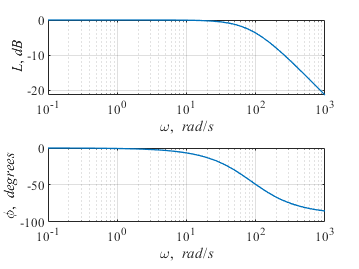

w = 10.^(-1:0.1:3);
s = 1i*w;
lin.Wop = 1./(lin.Tu*s);
lin.Wc1 = lin.Wop./(1+lin.Wop);
Lw = 20*log10(abs(lin.Wc1));
phi = angle(lin.Wc1)*180/pi;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

ax(1) = subplot(2,1,1);
plot(w,Lw,'Linewidth', 1)
hold on
grid on
set(ax(1), 'XScale', 'log')
xlabel('\omega\rm, \it rad\rm/\its')
ylabel('\it L\rm, \itdB')

ax(2) = subplot(2,1,2);
plot(w,phi,'Linewidth', 1)
hold on
grid on
set(ax(2), 'XScale', 'log')
xlabel('\omega\rm, \it rad\rm/\its')
ylabel('\phi, \it degrees')

linkaxes(ax, 'x')

disp(10^((max(Lw)-Lw(1))/20)/10^(Lw(1)/20))%показатель колебательности

    1.0000



## Биномиальный оптиум

bin.Tu = lin.Tu

bin = struct with fields:
    Tu: 0.0116


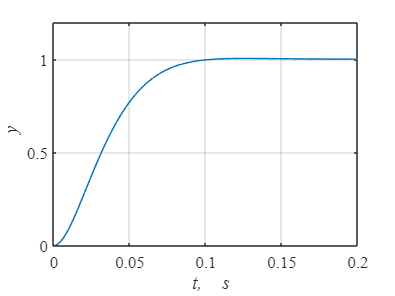


Tmdl = 0.2;
k = 1;

warning off
SimNew = sim('bin21.slx', 'ReturnWorkspaceOutputs','on');
warning on

t = SimNew.y(:,1);
y = SimNew.y(:,2);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,y,'Linewidth', 1)
hold on
grid on
xlabel('\it t,\rm \it s')
ylabel('\it y')

Время переходного процесса для входа в 5% зону t_tr

y0 = y(1);
yss = y(end);
D = 0.05*abs(y0-yss);
ind = abs(y-yss)>D;
h=figure;
%plot(t(ind), y(ind), 'LineWidth', 1)
tn = t(ind);
t0 = t(1);
t_tr = tn(end)-t0

t_tr = 0.0753

Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss)

dy = 0.0041

Время переходного процесса для входа в 2% зону t_tr

D2 = 0.02*abs(y0-yss);
ind = abs(y-yss)>D2;
h=figure;
%plot(t(ind), y(ind), 'LineWidth', 1)
tn = t(ind);
t0 = t(1);
t_tr2 = tn(end)-t0

t_tr2 = 0.0873

Реакция на лийнейно-возрастающие воздействие

load("data.mat")
k = 2;

warning off
SimNew = sim('bin21.slx', 'ReturnWorkspaceOutputs','on');
warning on

t = SimNew.y(:,1);
y = SimNew.y(:,2);
g = SimNew.y(:,3);
er = g-y;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

ax(1) = subplot(2,1,1)

ax =   1×2 Axes array:

    Axes    Axes


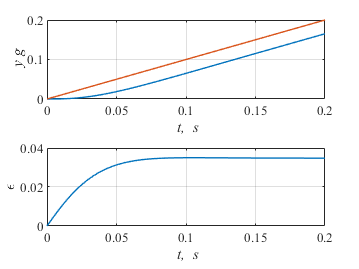

plot(t,y,'Linewidth', 1)
hold on
grid on
plot(t,g,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\it y\rm \itg')

ax(2) = subplot(2,1,2);
plot(t,er,'Linewidth', 1)
hold on
grid on
xlabel('\it t,\rm \it s')
ylabel('\epsilon')

linkaxes(ax, 'x')

Реакция на квадратичное воздействие

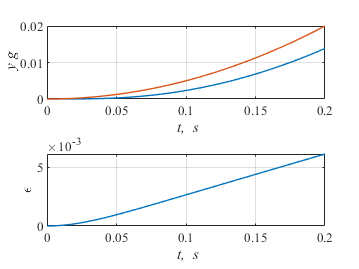

load("data.mat")
k = 3;

warning off
SimNew = sim('bin21.slx', 'ReturnWorkspaceOutputs','on');
warning on

t = SimNew.y(:,1);
y = SimNew.y(:,2);
g = SimNew.y(:,3);
er = g-y;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

ax(1) = subplot(2,1,1);
plot(t,y,'Linewidth', 1)
hold on
grid on
plot(t,g,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\it y\rm \itg')

ax(2) = subplot(2,1,2);
plot(t,er,'Linewidth', 1)
hold on
grid on
xlabel('\it t,\rm \it s')
ylabel('\epsilon')

linkaxes(ax, 'x')%привязывает оси, при увеличении графика верхнего, нижний тоже увеличивается

Запас по амплитуде, по фазе 

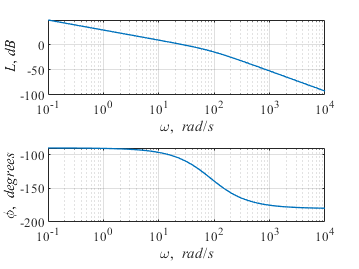

w = 10.^(-1:0.1:4);
s = 1i*w;
bin.Wop = 1./(3*bin.Tu^2*s.^2+3*bin.Tu*s);
Lw = 20*log10(abs(bin.Wop));
phi = angle(bin.Wop)*180/pi;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

ax(1) = subplot(2,1,1);
plot(w,Lw,'Linewidth', 1)
hold on
grid on
set(ax(1), 'XScale', 'log')
xlabel('\omega\rm, \it rad\rm/\its')
ylabel('\it L\rm, \itdB')

ax(2) = subplot(2,1,2);
plot(w,phi,'Linewidth', 1)
hold on
grid on
set(ax(2), 'XScale', 'log')
xlabel('\omega\rm, \it rad\rm/\its')
ylabel('\phi, \it degrees')

linkaxes(ax, 'x')

Запас колебательности

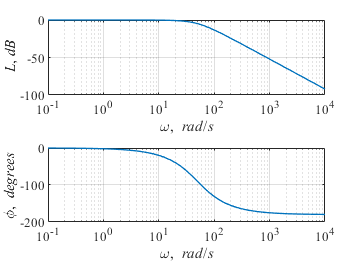

w = 10.^(-1:0.1:4);
s = 1i*w;
bin.Wop = 1./(3*bin.Tu^2*s.^2+3*bin.Tu*s);
bin.Wc1 = bin.Wop./(1+bin.Wop);
Lw = 20*log10(abs(bin.Wc1));
phi = angle(bin.Wc1)*180/pi;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

ax(1) = subplot(2,1,1);
plot(w,Lw,'Linewidth', 1)
hold on
grid on
set(ax(1), 'XScale', 'log')
xlabel('\omega\rm, \it rad\rm/\its')
ylabel('\it L\rm, \itdB')

ax(2) = subplot(2,1,2);
plot(w,phi,'Linewidth', 1)
hold on
grid on
set(ax(2), 'XScale', 'log')
xlabel('\omega\rm, \it rad\rm/\its')
ylabel('\phi, \it degrees')

linkaxes(ax, 'x')

disp(10^((max(Lw)-Lw(1))/20)/10^(Lw(1)/20))%показатель колебательности

    1.0000



## Технический оптиум

modal.Tu = lin.Tu

modal = struct with fields:
    Tu: 0.0116


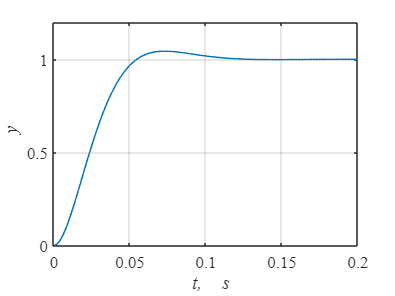


Tmdl = 0.2;
k = 1;

warning off
SimNew = sim('modal21.slx', 'ReturnWorkspaceOutputs','on');
warning on

t = SimNew.y(:,1);
y = SimNew.y(:,2);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,y,'Linewidth', 1)
hold on
grid on
xlabel('\it t,\rm \it s')
ylabel('\it y')

Время переходного процесса для входа в 5% зону t_tr

y0 = y(1);
yss = y(end);
D = 0.05*abs(y0-yss);
ind = abs(y-yss)>D;
h=figure;
%plot(t(ind), y(ind), 'LineWidth', 1)
tn = t(ind);
t0 = t(1);
t_tr = tn(end)-t0

t_tr = 0.0473

Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss)

dy = 0.0432

Время переходного процесса для входа в 2% зону t_tr

D2 = 0.02*abs(y0-yss);
ind = abs(y-yss)>D2;
h=figure;
%plot(t(ind), y(ind), 'LineWidth', 1)
tn = t(ind);
t0 = t(1);
t_tr2 = tn(end)-t0

t_tr2 = 0.0973

Реакция на лийнейно-возрастающие воздействие

load("data.mat")
k = 2;

warning off
SimNew = sim('modal21.slx', 'ReturnWorkspaceOutputs','on');
warning on

t = SimNew.y(:,1);
y = SimNew.y(:,2);
g = SimNew.y(:,3);
er = g-y;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

ax(1) = subplot(2,1,1)

ax =   1×2 Axes array:

    Axes    Axes


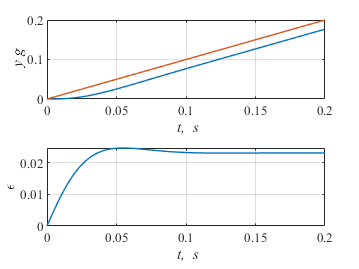

plot(t,y,'Linewidth', 1)
hold on
grid on
plot(t,g,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\it y\rm \itg')

ax(2) = subplot(2,1,2);
plot(t,er,'Linewidth', 1)
hold on
grid on
xlabel('\it t,\rm \it s')
ylabel('\epsilon')

linkaxes(ax, 'x')

Реакция на квадратичное воздействие

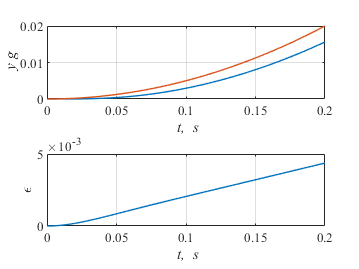

load("data.mat")
k = 3;

warning off
SimNew = sim('modal21.slx', 'ReturnWorkspaceOutputs','on');
warning on

t = SimNew.y(:,1);
y = SimNew.y(:,2);
g = SimNew.y(:,3);
er = g-y;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

ax(1) = subplot(2,1,1);
plot(t,y,'Linewidth', 1)
hold on
grid on
plot(t,g,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\it y\rm \itg')

ax(2) = subplot(2,1,2);
plot(t,er,'Linewidth', 1)
hold on
grid on
xlabel('\it t,\rm \it s')
ylabel('\epsilon')

linkaxes(ax, 'x')%привязывает оси, при увеличении графика верхнего, нижний тоже увеличивается

Запас по амплитуде, по фазе 

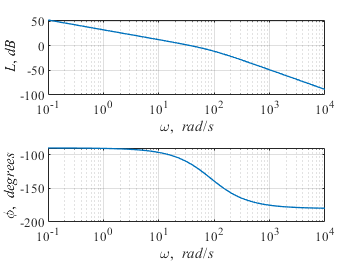

w = 10.^(-1:0.1:4);
s = 1i*w;
modal.Wop = 1./(2*modal.Tu^2*s.^2+2*modal.Tu*s);
Lw = 20*log10(abs(modal.Wop));
phi = angle(modal.Wop)*180/pi;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

ax(1) = subplot(2,1,1);
plot(w,Lw,'Linewidth', 1)
hold on
grid on
set(ax(1), 'XScale', 'log')
xlabel('\omega\rm, \it rad\rm/\its')
ylabel('\it L\rm, \itdB')

ax(2) = subplot(2,1,2);
plot(w,phi,'Linewidth', 1)
hold on
grid on
set(ax(2), 'XScale', 'log')
xlabel('\omega\rm, \it rad\rm/\its')
ylabel('\phi, \it degrees')

linkaxes(ax, 'x')

Показатель колебательности

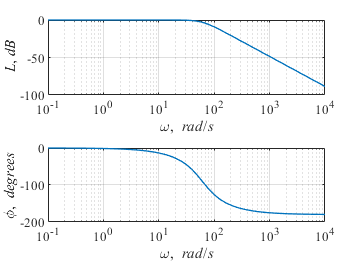

w = 10.^(-1:0.1:4);
s = 1i*w;
modal.Wop = 1./(2*modal.Tu^2*s.^2+2*modal.Tu*s);
modal.Wc1 = modal.Wop./(1+modal.Wop);
Lw = 20*log10(abs(modal.Wc1));
phi = angle(modal.Wc1)*180/pi;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

ax(1) = subplot(2,1,1);
plot(w,Lw,'Linewidth', 1)
hold on
grid on
set(ax(1), 'XScale', 'log')
xlabel('\omega\rm, \it rad\rm/\its')
ylabel('\it L\rm, \itdB')

ax(2) = subplot(2,1,2);
plot(w,phi,'Linewidth', 1)
hold on
grid on
set(ax(2), 'XScale', 'log')
xlabel('\omega\rm, \it rad\rm/\its')
ylabel('\phi, \it degrees')

linkaxes(ax, 'x')

disp(10^((max(Lw)-Lw(1))/20)/10^(Lw(1)/20))%показатель колебательности

    1.0000



## Симметричный оптиум

simtr.Tu = lin.Tu

simtr = struct with fields:
    Tu: 0.0116


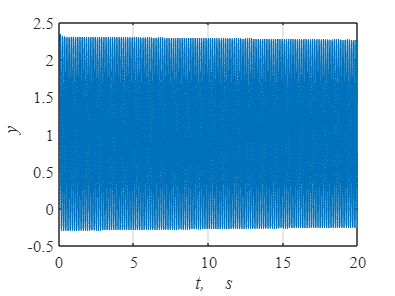


Tmdl = 1;
k = 1;

warning off
SimNew = sim('simtr21.slx', 'ReturnWorkspaceOutputs','on');
warning on

t = SimNew.y(:,1);
y = SimNew.y(:,2);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,y,'Linewidth', 1)
hold on
grid on
xlabel('\it t,\rm \it s')
ylabel('\it y')

Время переходного процесса для входа в 5% зону t_tr

y0 = y(1);
yss = y(end);
D = 0.05*abs(y0-yss);
ind = abs(y-yss)>D;
h=figure;
%plot(t(ind), y(ind), 'LineWidth', 1)
tn = t(ind);
t0 = t(1);
t_tr = tn(end)-t0

t_tr = 19.9983

Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss)

dy = 2.1274

Время переходного процесса для входа в 2% зону t_tr

D2 = 0.02*abs(y0-yss);
ind = abs(y-yss)>D2;
h=figure;
%plot(t(ind), y(ind), 'LineWidth', 1)
tn = t(ind);
t0 = t(1);
t_tr2 = tn(end)-t0

t_tr2 = 19.9993

Реакция на лийнейно-возрастающие воздействие

load("data.mat")
k = 2;

warning off
SimNew = sim('simtr21.slx', 'ReturnWorkspaceOutputs','on');
warning on

t = SimNew.y(:,1);
y = SimNew.y(:,2);
g = SimNew.y(:,3);
er = g-y;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

ax(1) = subplot(2,1,1)

ax =   1×2 Axes array:

    Axes    Axes


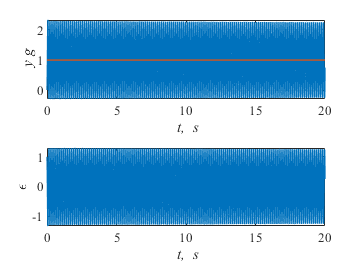

plot(t,y,'Linewidth', 1)
hold on
grid on
plot(t,g,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\it y\rm \itg')

ax(2) = subplot(2,1,2);
plot(t,er,'Linewidth', 1)
hold on
grid on
xlabel('\it t,\rm \it s')
ylabel('\epsilon')

linkaxes(ax, 'x')

Реакция на квадратичное воздействие

load("data.mat")
k = 3;

warning off
SimNew = sim('simtr21.slx', 'ReturnWorkspaceOutputs','on');
warning on

t = SimNew.y(:,1);
y = SimNew.y(:,2);
g = SimNew.y(:,3);
er = g-y;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

ax(1) = subplot(2,1,1);
plot(t,y,'Linewidth', 1)
hold on
grid on
plot(t,g,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\it y\rm \itg')

ax(2) = subplot(2,1,2);
plot(t,er,'Linewidth', 1)
hold on
grid on
xlabel('\it t,\rm \it s')
ylabel('\epsilon')

linkaxes(ax, 'x')%привязывает оси, при увеличении графика верхнего, нижний тоже увеличивается

Запас по амплитуде, по фазе 

w = 10.^(-1:0.1:4);
s = 1i*w;
simtr.Wop = (4*simtr.Tu*s+1)./(8*simtr.Tu^3*s.^3+8*simtr.Tu^2*s.^2);
Lw = 20*log10(abs(simtr.Wop));
phi = angle(simtr.Wop)*180/pi;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

ax(1) = subplot(2,1,1);
plot(w,Lw,'Linewidth', 1)
hold on
grid on
set(ax(1), 'XScale', 'log')
xlabel('\omega\rm, \it rad\rm/\its')
ylabel('\it L\rm, \itdB')

ax(2) = subplot(2,1,2);
plot(w,phi,'Linewidth', 1)
hold on
grid on
set(ax(2), 'XScale', 'log')
xlabel('\omega\rm, \it rad\rm/\its')
ylabel('\phi, \it degrees')

linkaxes(ax, 'x')

subplot(2,1,1)
ax2 = gca;
chart = ax2.Children(1);
datatip(chart,31.62,3.799);

Показатель колебательности

w = 10.^(-1:0.1:4);
s = 1i*w;
simtr.Wop = (4*simtr.Tu*s+1)./(8*simtr.Tu^3*s.^3+8*simtr.Tu^2*s.^2);
simtr.Wc1 = simtr.Wop./(1+simtr.Wop);
Lw = 20*log10(abs(simtr.Wc1));
phi = angle(simtr.Wc1)*180/pi;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

ax(1) = subplot(2,1,1);
plot(w,Lw,'Linewidth', 1)
hold on
grid on
set(ax(1), 'XScale', 'log')
xlabel('\omega\rm, \it rad\rm/\its')
ylabel('\it L\rm, \itdB')

ax(2) = subplot(2,1,2);
plot(w,phi,'Linewidth', 1)
hold on
grid on
set(ax(2), 'XScale', 'log')
xlabel('\omega\rm, \it rad\rm/\its')
ylabel('\phi, \it degrees')


MathWorks::System::IUserException in WebControllerFactory::create(): [Error using matlab.ui.internal.componentframework.WebControllerFactory/checkPreconditions
Invalid superclass name.

Error in matlab.ui.internal.componentframework.WebControllerFactory/create (line 92)
                checkPreconditions( obj, 

disp(10^((max(Lw)-Lw(1))/20)/10^(Lw(1)/20))%показатель колебательности

## Астатизм третьего порядка (надо сделать)

ast.Tu = lin.Tu

ast = struct with fields:
    Tu: 0.0116


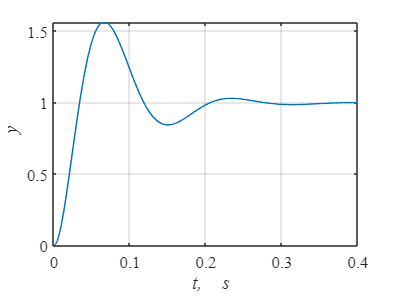

Tmdl = 0.4;
k = 1;

warning off
SimNew = sim('ast21.slx', 'ReturnWorkspaceOutputs','on');
warning on

t = SimNew.y(:,1);
y = SimNew.y(:,2);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,y,'Linewidth', 1)
hold on
grid on
xlabel('\it t,\rm \it s')
ylabel('\it y')

Время переходного процесса для входа в 5% зону t_tr

y0 = y(1);
yss = y(end);
D = 0.05*abs(y0-yss);
ind = abs(y-yss)>D;
h=figure;
%plot(t(ind), y(ind), 'LineWidth', 1)
tn = t(ind);
t0 = t(1);
t_tr = tn(end)-t0

t_tr = 0.1883

Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss)

dy = 0.5638

Время переходного процесса для входа в 2% зону t_tr

D2 = 0.02*abs(y0-yss);
ind = abs(y-yss)>D2;
h=figure;
%plot(t(ind), y(ind), 'LineWidth', 1)
tn = t(ind);
t0 = t(1);
t_tr2 = tn(end)-t0

t_tr2 = 0.2533

Реакция на лийнейно-возрастающие воздействие

load("data.mat")
k = 2;

warning off
SimNew = sim('ast21.slx', 'ReturnWorkspaceOutputs','on');
warning on

t = SimNew.y(:,1);
y = SimNew.y(:,2);
g = SimNew.y(:,3);
er = g-y;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

ax(1) = subplot(2,1,1)

ax =   1×2 Axes array:

    Axes    Axes


plot(t,y,'Linewidth', 1)
hold on
grid on
plot(t,g,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\it y\rm \itg')

ax(2) = subplot(2,1,2);
plot(t,er,'Linewidth', 1)
hold on
grid on
xlabel('\it t,\rm \it s')
ylabel('\epsilon')

linkaxes(ax, 'x')

Реакция на квадратичное воздействие

load("data.mat")
k = 3;

warning off
SimNew = sim('ast21.slx', 'ReturnWorkspaceOutputs','on');
warning on

t = SimNew.y(:,1);
y = SimNew.y(:,2);
g = SimNew.y(:,3);
er = g-y;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

ax(1) = subplot(2,1,1);
plot(t,y,'Linewidth', 1)
hold on
grid on
plot(t,g,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\it y\rm \itg')

ax(2) = subplot(2,1,2);
plot(t,er,'Linewidth', 1)
hold on
grid on
xlabel('\it t,\rm \it s')
ylabel('\epsilon')

linkaxes(ax, 'x')%привязывает оси, при увеличении графика верхнего, нижний тоже увеличивается

Запас по амплитуде, по фазе 

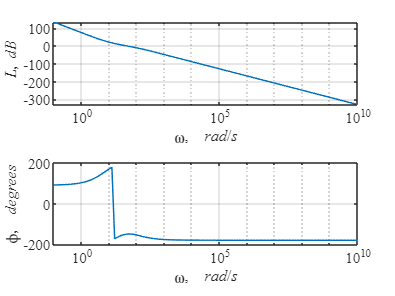

w = 10.^(-1:0.1:10);
s = 1i*w;
ast.Wop = (64*ast.Tu^2*s.^2+20*ast.Tu*s+1)./(128*ast.Tu^4*s.^4+128*ast.Tu^3*s.^3);
Lw = 20*log10(abs(ast.Wop));
phi = angle(ast.Wop)*180/pi;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

ax(1) = subplot(2,1,1);
plot(w,Lw,'Linewidth', 1)
hold on
grid on
set(ax(1), 'XScale', 'log')
xlabel('\omega\rm, \it rad\rm/\its')
ylabel('\it L\rm, \itdB')

ax(2) = subplot(2,1,2);
plot(w,phi,'Linewidth', 1)
hold on
grid on
set(ax(2), 'XScale', 'log')
xlabel('\omega\rm, \it rad\rm/\its')
ylabel('\phi, \it degrees')

Показатель колебательности

w = 10.^(-1:0.1:4);
s = 1i*w;
ast.Wop = (64*ast.Tu^2*s.^2+20*ast.Tu*s+1)./(128*ast.Tu^4*s.^4+128*ast.Tu^3*s.^3);
ast.Wc1 = ast.Wop./(1+ast.Wop)

ast = struct with fields:
     Tu: 0.0116
    Wop: [-1.1031e+05 + 5.0048e+06i -6.9603e+04 + 2.5083e+06i -4.3917e+04 + 1.2570e+06i -2.7710e+04 + 6.2996e+05i -1.7484e+04 + 3.1568e+05i -1.1032e+04 + 1.5818e+05i -6.9606e+03 + 7.9250e+04i -4.3920e+03 + 3.9697e+04i -2.7713e+03 + 1.9878e+04i … ]
    Wc1: [1.0000 + 0.0000i 1.0000 + 0.0000i 1.0000 + 0.0000i 1.0000 + 0.0000i 1.0000 + 0.0000i 1.0000 + 0.0000i 1.0000 + 0.0000i 1.0000 + 0.0000i 1.0000 + 0.0000i 1.0000 + 0.0001i 1.0000 + 0.0002i 1.0001 + 0.0004i 1.0003 + 0.0007i 1.0006 + 0.0014i … ]


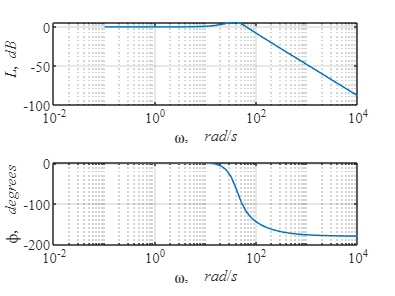

Lw = 20*log10(abs(ast.Wc1));
phi = angle(ast.Wc1)*180/pi;

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

ax(1) = subplot(2,1,1);
plot(w,Lw,'Linewidth', 1)
hold on
grid on
set(ax(1), 'XScale', 'log')
xlabel('\omega\rm, \it rad\rm/\its')
ylabel('\it L\rm, \itdB')

ax(2) = subplot(2,1,2);
plot(w,phi,'Linewidth', 1)
hold on
grid on
set(ax(2), 'XScale', 'log')
xlabel('\omega\rm, \it rad\rm/\its')
ylabel('\phi, \it degrees')


disp(10^((max(Lw)-Lw(1))/20)/10^(Lw(1)/20))%показатель колебательности

    2.0571

